xyz_camera_calibration.mlx

Alex Elias

Uses UWB distance readings to calculate XYZ of camera/UWB calibration checkerboard

## Read in UWB readings from ROS

bag = rosbag('E:/2021-08-26-11-42-19.bag')

bag =   BagSelection with properties:

           FilePath: 'E:\2021-08-26-11-42-19.bag'
          StartTime: 1.6300e+09
            EndTime: 1.6300e+09
        NumMessages: 153965
    AvailableTopics: [45×3 table]
    AvailableFrames: {23×1 cell}
        MessageList: [153965×4 table]


bag.AvailableTopics

ans = 45×3 table
                                                    NumMessages                 MessageType                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                      MessageDefinition                                                  


bSel_x = select(bag,'Topic','/ridgeback/uwb_serial_front');
msgs_x = readMessages(bSel_x)

t_x = bSel_x.MessageList.Time

t_x = 	1.0e+09 *

    1.6300
    1.6300
    1.6300
    1.6300
    1.6300
    1.6300
    1.6300
    1.6300
    1.6300
    1.6300



bSel_y = select(bag,'Topic','/ridgeback/uwb_serial_back');
msgs_y = readMessages(bSel_y)

t_y = bSel_y.MessageList.Time

t_y = 	1.0e+09 *

    1.6300
    1.6300
    1.6300
    1.6300
    1.6300
    1.6300
    1.6300
    1.6300
    1.6300
    1.6300


## Parse readings, find average distances and statistics

[anchor_names, anchor_locs] = anchor_info(msgs_x)

anchor_names = 4×1 string array
    "2A32"
    "29EF"
    "2ED1"
    "0D40"


anchor_locs =    10.9700   10.7600    2.7600         0
         0    4.2400    4.3200         0
    3.2500    3.1400    3.2900    3.5700


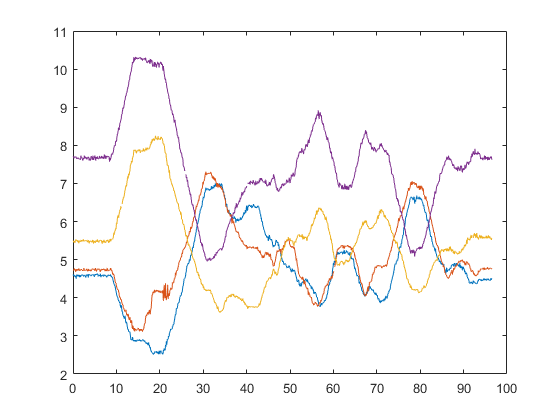

dist_mat_x = get_distances(msgs_x, anchor_names);
dist_mat_y = get_distances(msgs_y, anchor_names);

t_0 = min([t_x; t_y]);
t_x_offset = t_x-t_0;
t_y_offset = t_y-t_0;

plot(t_x_offset, dist_mat_x)

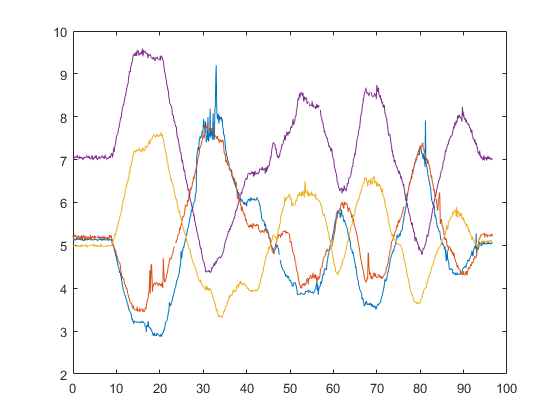

plot(t_y_offset, dist_mat_y)


t_start = 0

t_start = 0

t_end = 5

t_end = 5

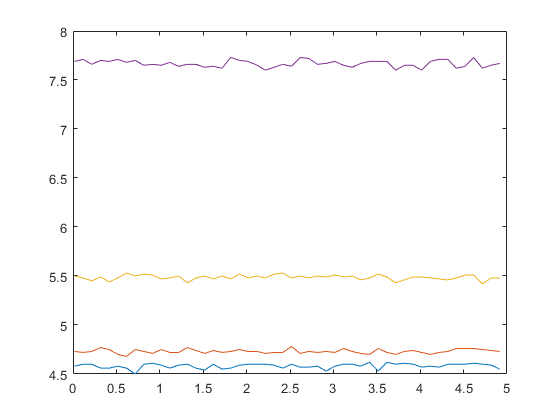


ind_x =  t_x_offset >= t_start & t_x_offset <= t_end;
ind_y =  t_y_offset >= t_start & t_y_offset <= t_end;

t_x_offset = t_x_offset(ind_x);
dist_mat_x = dist_mat_x(ind_x, :);
t_y_offset = t_y_offset(ind_y);
dist_mat_y = dist_mat_y(ind_y, :);

plot(t_x_offset, dist_mat_x)

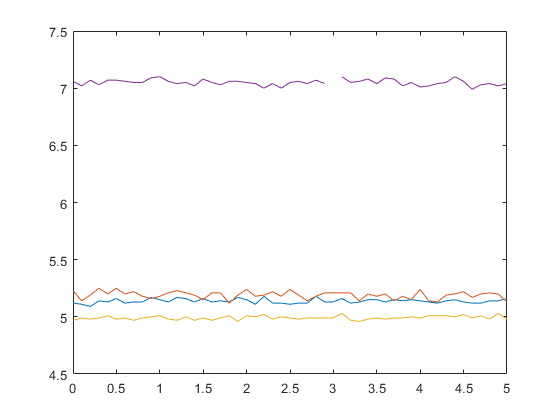

plot(t_y_offset, dist_mat_y)


avg_dists_x = mean(dist_mat_x,'omitnan')

avg_dists_x =     4.5820    4.7308    5.4858    7.6672


std(dist_mat_x,'omitnan')*1e3

ans =    25.1526   21.0771   24.8333   34.8197



avg_dists_y = mean(dist_mat_y,'omitnan')

avg_dists_y =     5.1375    5.1910    4.9918    7.0496


std(dist_mat_y,'omitnan')*1e3

ans =    19.3745   33.0608   16.5778   25.7904


## Localize checkerboard

cal_map = antenna_cal_values()

cal_map =   Map with properties:

        Count: 18
      KeyType: char
    ValueType: double



anchor_offsets = [  cal_map(anchor_names(1))
                    cal_map(anchor_names(2))
                    cal_map(anchor_names(3))
                    cal_map(anchor_names(4))]

anchor_offsets =     0.0650
    0.0420
    0.0620
    0.0940


tag_offset_x = cal_map('0D8F')

tag_offset_x = 0.0770

tag_offset_y = cal_map('0CAD')

tag_offset_y = 0.1250


dists_x_cal = avg_dists_x + anchor_offsets' + tag_offset_x

dists_x_cal =     4.7240    4.8498    5.6248    7.8382


dists_y_cal = avg_dists_y + anchor_offsets' + tag_offset_y

dists_y_cal =     5.3275    5.3580    5.1788    7.2686



[pos, err] = tag_pair_min_z(dists_x_cal', dists_y_cal', [0.5054; 0.0254], [-0.17405; 0.0254], anchor_locs)

pos =     6.7080
    1.7215
    0.9471
    0.0107


err = 0.0058


1e2* sqrt(err/4)

ans = 3.7946

## Append list of recorded XYZ positions

%%%%


## Write list of XYZ positions to CSV file

%%%%


function [anchor_names, anchor_locs] = anchor_info(msgs)
% Find the 4 anchors
for i = 1:length(msgs)
    line = msgs{i}.Data;
    line_sp = split(line, ',');
    if line_sp{2} == '4' % Got 4 readings this line
        anchor_names = string([line_sp{4}; line_sp{10}; line_sp{16}; line_sp{22}]);
        line_sp = str2double(line_sp);
        anchor_locs = [line_sp(5) line_sp(11) line_sp(17) line_sp(23)
                       line_sp(6) line_sp(12) line_sp(18) line_sp(24)
                       line_sp(7) line_sp(13) line_sp(19) line_sp(25)];
        break
    end
end
end

function dist_mat = get_distances(msgs, anchors)
dist_mat = NaN(length(msgs), 4);
for i = 1:length(msgs)
        line = msgs{i}.Data;
        if line == ""
            continue
        end
        data = split(line, ',');
        % Anchor labels are at 4,10,16,22
        % Anchor distances are at 8, 14, 20, 26
        N_anch_i = str2double(data{2});
        
        if N_anch_i >= 1
            dist_mat(i, anchors == data{4}) = str2double(data{8});
        end
        if N_anch_i >= 2
            dist_mat(i, anchors == data{10}) = str2double(data{14});
        end
        if N_anch_i >= 3
            dist_mat(i, anchors == data{16}) = str2double(data{20});
        end
        if N_anch_i == 4
            dist_mat(i, anchors == data{22}) = str2double(data{26});
        end
end
end